close all;
clear all;
clc;

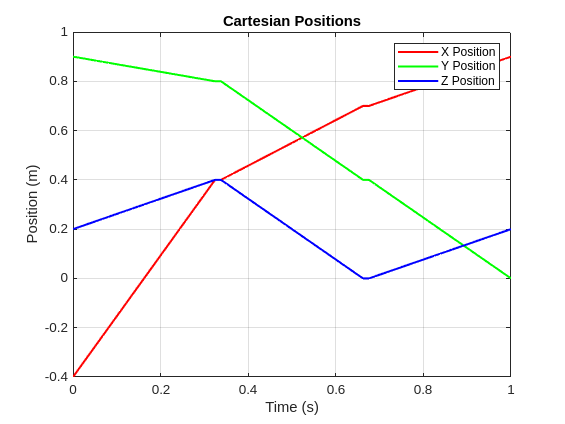

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints
waypoints = [ -0.4, 0.4, 0.7, 0.9;  % X positions
              0.9, 0.8, 0.4, 0.0;   % Y positions
              0.2, 0.4, 0.0, 0.2];  % Z positions

% Number of samples per segment
numSamplesPerSegment = 25;

% Initialize variables for storing interpolated points and configurations
interpolatedPoints = [];
interpolatedConfigs = [];

% Interpolate between each pair of waypoints
for i = 1:size(waypoints, 2)-1
    % Linear interpolation between two waypoints
    t = linspace(0, 1, numSamplesPerSegment);
    segmentPoints = (1 - t)' * waypoints(:, i)' + t' * waypoints(:, i+1)';
    interpolatedPoints = [interpolatedPoints; segmentPoints]; % Append to the total points
    
    % Compute IK for the segment
    for j = 1:size(segmentPoints, 1)
        T = trvec2tform(segmentPoints(j, :));  % Convert to homogeneous transformation
        [theta, ~] = ik('tool0', T, weights, initialGuess);
        interpolatedConfigs = [interpolatedConfigs; theta];
        initialGuess = theta;  % Update initial guess for the next step
    end
end

% Time vector (uniformly spaced for all points)
time = linspace(0, 1, size(interpolatedPoints, 1));

% Compute Cartesian velocities and accelerations
cartesianVelocities = diff(interpolatedPoints) ./ diff(time');  % Approximate Cartesian velocities
cartesianAccelerations = diff(cartesianVelocities) ./ diff(time(1:end-1)'); % Approximate Cartesian accelerations

% Add zeros for alignment with time vector (since diff reduces length)
cartesianVelocities = [cartesianVelocities; zeros(1, size(cartesianVelocities, 2))];
cartesianAccelerations = [cartesianAccelerations; zeros(2, size(cartesianAccelerations, 2))];

% Plot Cartesian Positions
f1 = figure;
plot(time, interpolatedPoints(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(time, interpolatedPoints(:, 2), 'g', 'LineWidth', 1.5);
plot(time, interpolatedPoints(:, 3), 'b', 'LineWidth', 1.5);
title('Cartesian Positions');
xlabel('Time (s)');
ylabel('Position (m)');
legend('X Position', 'Y Position', 'Z Position');
grid on;

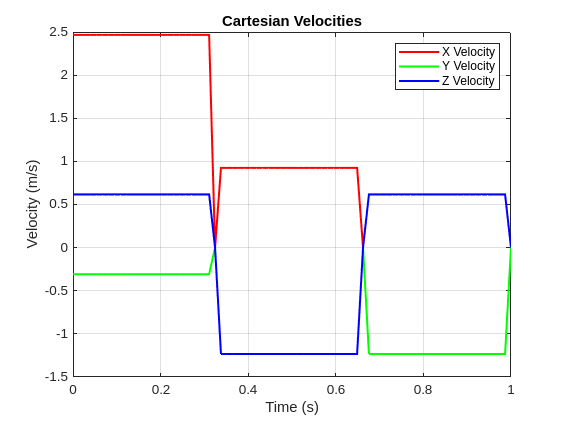

savefig(f1,"ikp.fig");   % saves the figure  

% Plot Cartesian Velocities
f2 = figure;
plot(time, cartesianVelocities(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(time, cartesianVelocities(:, 2), 'g', 'LineWidth', 1.5);
plot(time, cartesianVelocities(:, 3), 'b', 'LineWidth', 1.5);
title('Cartesian Velocities');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend('X Velocity', 'Y Velocity', 'Z Velocity');
grid on;

savefig(f2,"ikv.fig");   % saves the figure 

% Plot Cartesian Accelerations
f3 = figure;
plot(time, cartesianAccelerations(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(time, cartesianAccelerations(:, 2), 'g', 'LineWidth', 1.5);
plot(time, cartesianAccelerations(:, 3), 'b', 'LineWidth', 1.5);
title('Cartesian Accelerations');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend('X Acceleration', 'Y Acceleration', 'Z Acceleration');
grid on;

savefig(f3,"ika.fig");   % saves the figure 

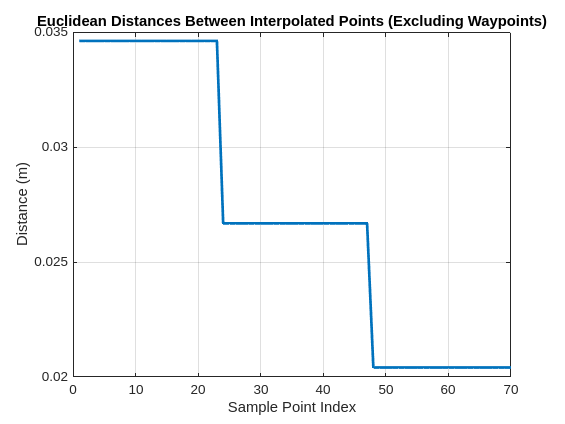

% Exclude waypoints from the interpolated points for distance calculation
excludeControlPoints = false(size(interpolatedPoints, 1), 1);
for i = 1:size(waypoints, 2)
    for j = 1:size(interpolatedPoints, 1)
        % Check if the interpolated point matches the waypoint
        if all(abs(interpolatedPoints(j,:) - waypoints(:, i)') < 1e-6)
            excludeControlPoints(j) = true;  % Mark the waypoint to exclude
            break;
        end
    end
end

% Exclude the waypoints (control points) from the interpolated points
interpolatedPointsWithoutWaypoints = interpolatedPoints(~excludeControlPoints, :);

% Compute Euclidean distances between consecutive interpolated points (excluding waypoints)
numPoints = size(interpolatedPointsWithoutWaypoints, 1);
distances = zeros(numPoints-1, 1); % Preallocate distance array
for i = 1:numPoints-1
    % Compute Euclidean distance between consecutive points
    distances(i) = norm(interpolatedPointsWithoutWaypoints(i+1, :) - interpolatedPointsWithoutWaypoints(i, :));
end

% Plot Euclidean distances between sample points (excluding waypoints)
figure;
plot(1:length(distances), distances, 'LineWidth', 2);
title('Euclidean Distances Between Interpolated Points (Excluding Waypoints)');
xlabel('Sample Point Index');
ylabel('Distance (m)');
grid on;

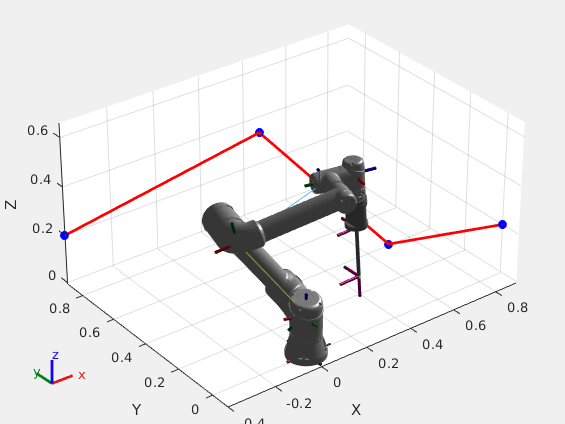

% Visualize the Robot's Path
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'r-', 'LineWidth', 2);
plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo', 'MarkerFaceColor', 'b');

% Initial axis limits
xlim([-0.5 1]);
ylim([-0.5 1]);
zlim([-0.2 0.6]); % Start with a reasonable Z limit
grid on;
axis equal;
view(3);


% %% Animate the Robot Motion and Adjust Z-Axis Dynamically
% robotAnimation = VideoWriter('robot_animation.avi', 'Motion JPEG AVI');
% open(robotAnimation);
% 
% % Initial Z limit
% zMin = -0.2;
% zMax = 0.6;
% 
% for i = 1:size(interpolatedConfigs, 1)
%     % Update robot configuration
%     show(ur5e, interpolatedConfigs(i, :), 'Frames', 'on', 'PreservePlot', false);
% 
%     % Update Z axis dynamically based on the robot's current position
%     currentZ = interpolatedPoints(i, 3); % Z-coordinate of the robot's end effector
% 
%     % Modify Z limits to zoom out if the Z position is approaching the edge
%     zMin = min(zMin, currentZ - 0.2); % Slight zoom-out in Z
%     zMax = max(zMax, currentZ + 0.2); % Slight zoom-out in Z
% 
%     % Set updated axis limits
%     axis([-0.5 1 -0.5 1 zMin zMax]);
% 
%     % Capture the frame for the animation
%     frame = getframe(gcf);
%     writeVideo(robotAnimation, frame);
% 
%     pause(0.1); % Adjust for smooth animation
% end

% Close video file
close(robotAnimation);

Unrecognized function or variable 'robotAnimation'.